# Machine Learning From Coursera

Exercise 1 Multi_features

In this exercise, I use the data containing two features namely- size of house in square feet and no.of bed room.By following the steps in ex1.pdf, I'll compute the price of a house based on the predicted values after training the model.

## Step1 Load the Data

clear all;close all
data=load('ex1data2.txt');
x=data(:,1:2);y=data(:,3);
fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf('x=[%.0f %.0f],y=%.0f \n',[x(1:10,:) y(1:10,:)]')

x=[2104 3],y=399900 
x=[1600 3],y=329900 
x=[2400 3],y=369000 
x=[1416 2],y=232000 
x=[3000 4],y=539900 
x=[1985 4],y=299900 
x=[1534 3],y=314900 
x=[1427 3],y=198999 
x=[1380 3],y=212000 
x=[1494 3],y=242500 


You will see that the value of the price is 1000 times larger than the no. of bedroom. We will use a Feature Normalization method to reduce the gap. Then,we'll use both the Gradient Descent and the equation to train our model.

%adding one columns of ones to the x
X=[ones(length(y),1),x]

X =            1        2104           3
           1        1600           3
           1        2400           3
           1        1416           2
           1        3000           4
           1        1985           4
           1        1534           3
           1        1427           3
           1        1380           3
           1        1494           3


%set the number of iterations
iterations=400;
alpha=0.01;
%Scale features and set them to zero mean
[X_norm mu sigma]=Normalize_feature(X);

theta=zeros(3,1);
[theta,J_history]=GradientDescent(X_norm,y,theta,alpha,iterations);
fprintf('Theta computed from gradient descent:  %f\n')

Theta computed from gradient descent:  

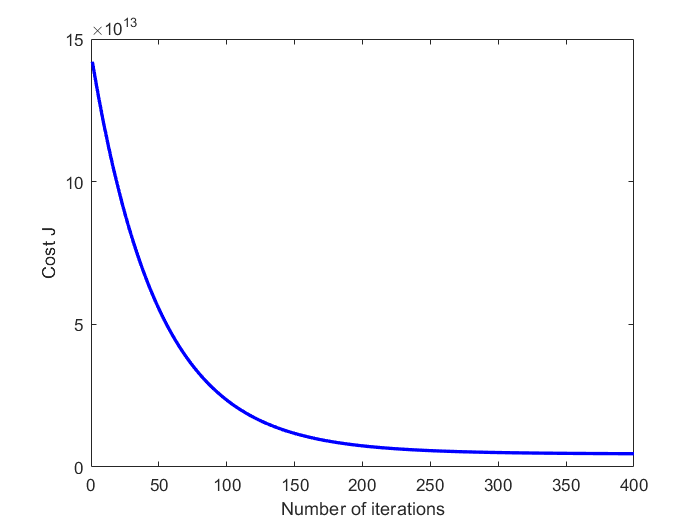

plot(1:size(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');   

we plot the graph to see the descending values of J on every iterations. J should be decreased on every iterations until it reaches the global minium.

fprintf('%.0f\n',theta);

334302
100087
3674


Using the Gradient Descent method to estimate the price of a 1650 sq-ft, 3 bedroom. 

We first transfrom these values to normalized feature.

x1=(1650-mu(2))/sigma(2);
x2=(3-mu(3))/sigma(3);
price=[1 x1 x2]*theta;
fprintf(['[Predicted price of a 1650 sq-ft, 3 bedroom house ' ...
    '(using the gradient descent):\n $ %f\n'],price);

[Predicted price of a 1650 sq-ft, 3 bedroom house (using the gradient descent):
 $ 289314.620338


Using the Normal Equation method, we again compute the values of theta

theta=NormalEquation(X,y);
fprintf('Theta computed from Normal Equation:  %f\n');

Theta computed from Normal Equation:  

fprintf('%.0f\n',theta);

89598
139
-8738


function[X_norm,mu,sigma]=Normalize_feature(X)
mu=mean(X);
sigma=std(X);
X_norm=(X-mu)./sigma;
X_norm(:,1)=1;
end

function J=Cost(X,y,theta)
m=length(y);
h=X*theta;
sqrError=(h-y).^2;
J=(1/2*m)*sum(sqrError);
end

function [theta,J_history]=GradientDescent(X,y,theta,alpha,iterations)
m=length(y);
J_history=zeros(iterations,1);
for iterations=1:iterations
    h=X*theta;
    error=(h-y);
    theta=theta-((alpha/m)*X'*error);
    J_history(iterations)=Cost(X,y,theta);
    
end
end

function[theta]=NormalEquation(x,y)
theta = zeros(size(x, 2), 1);
theta=pinv(x'*x)*x'*y;
end